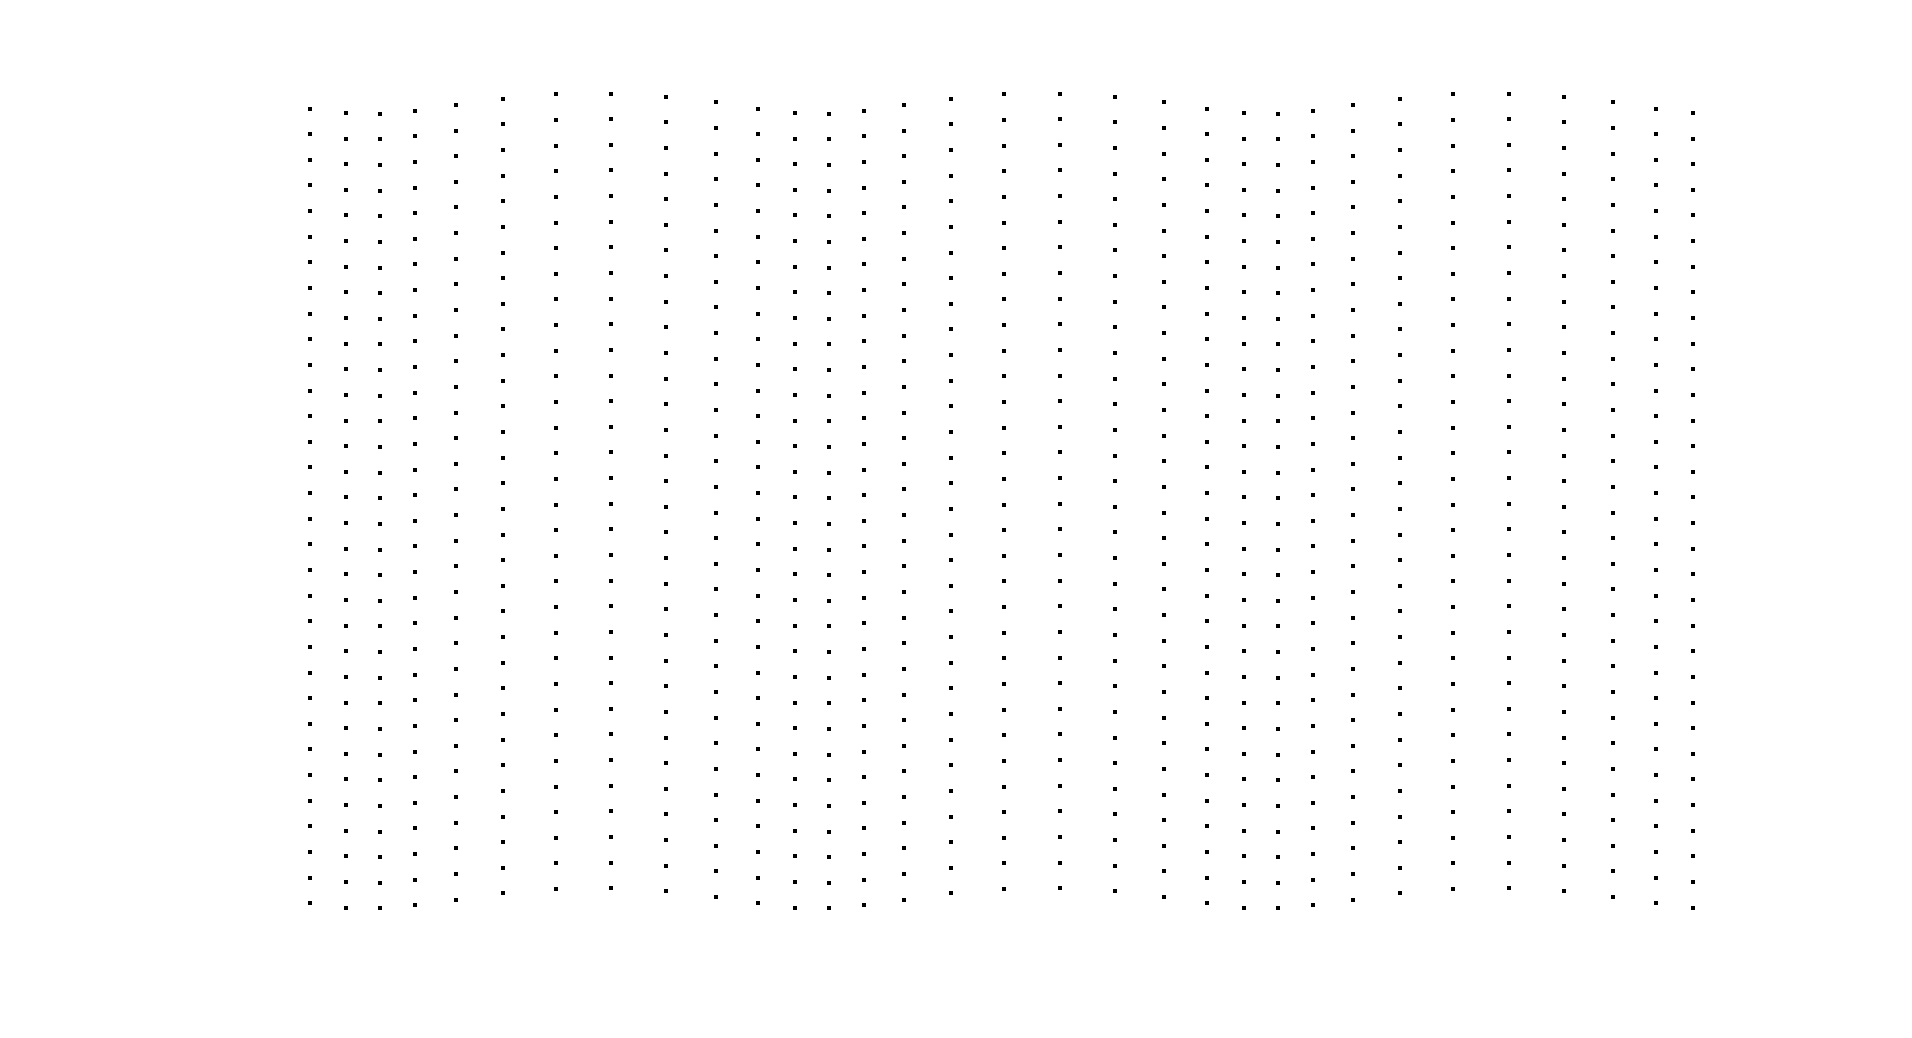

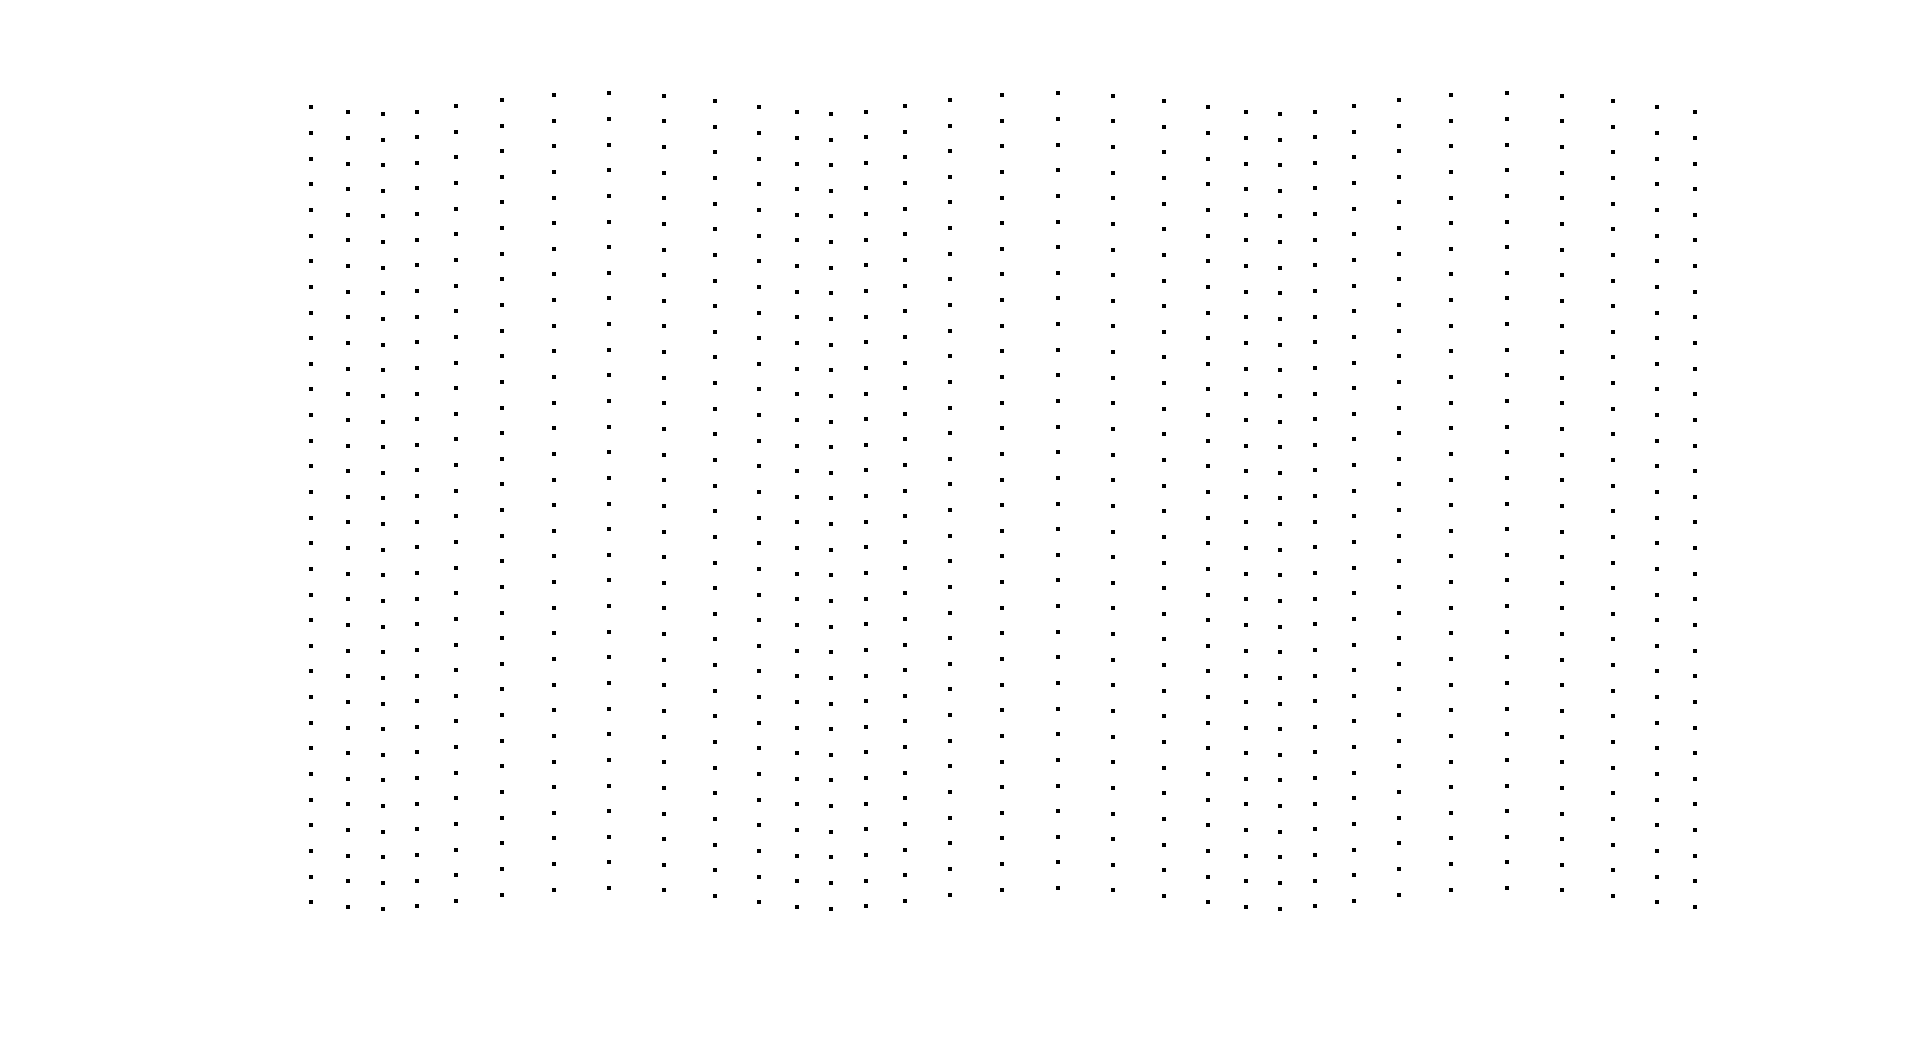

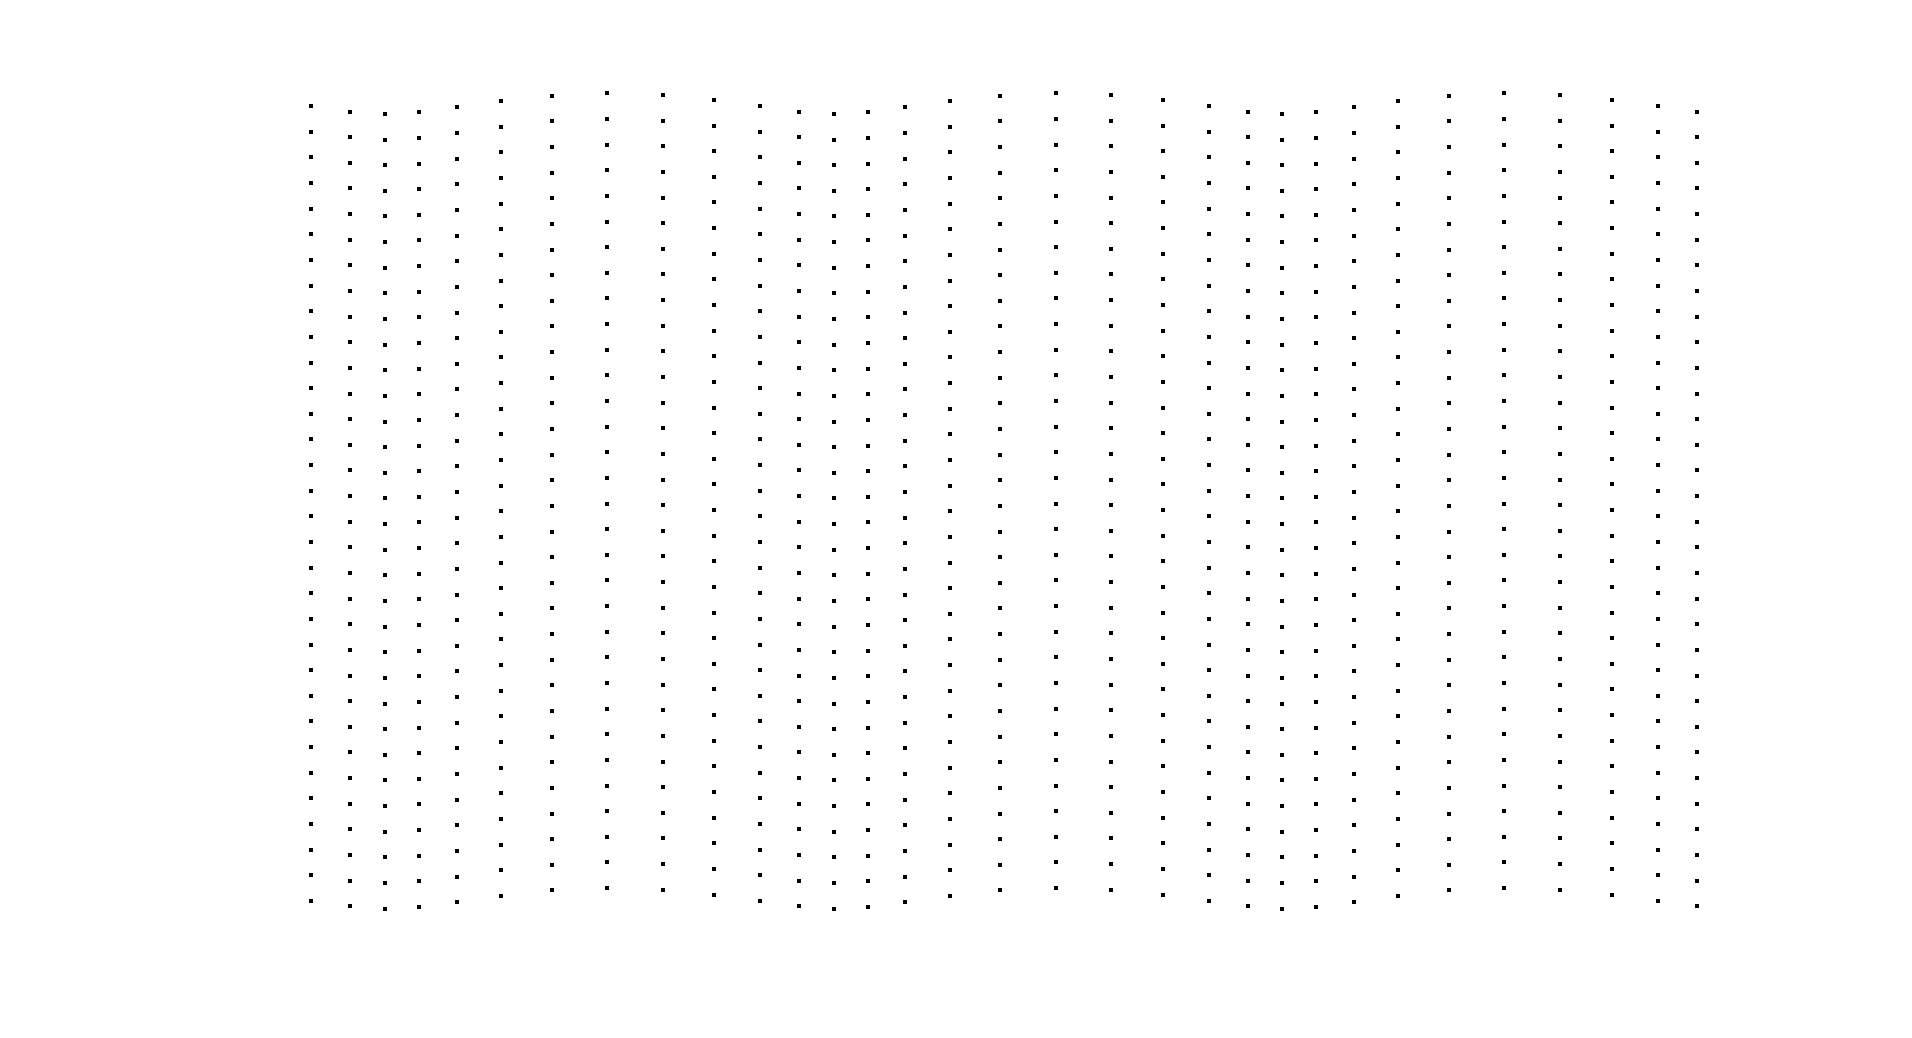

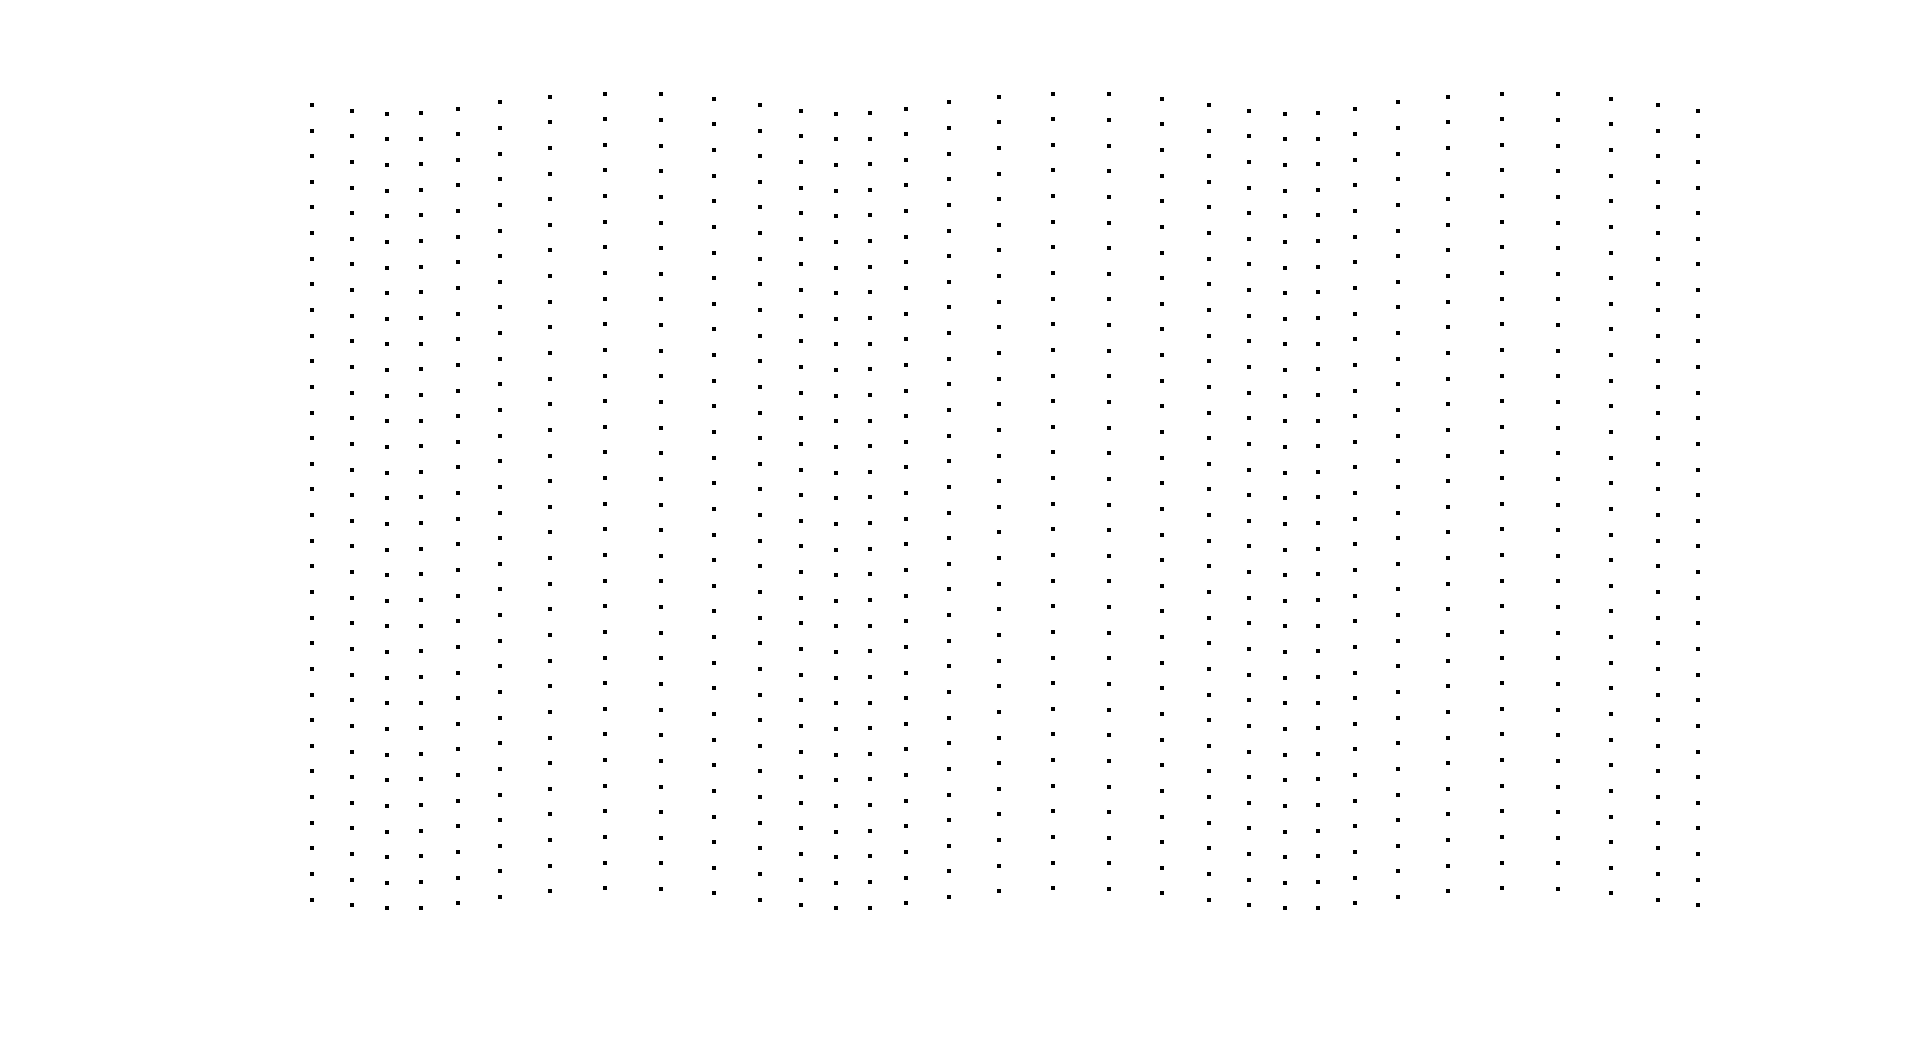

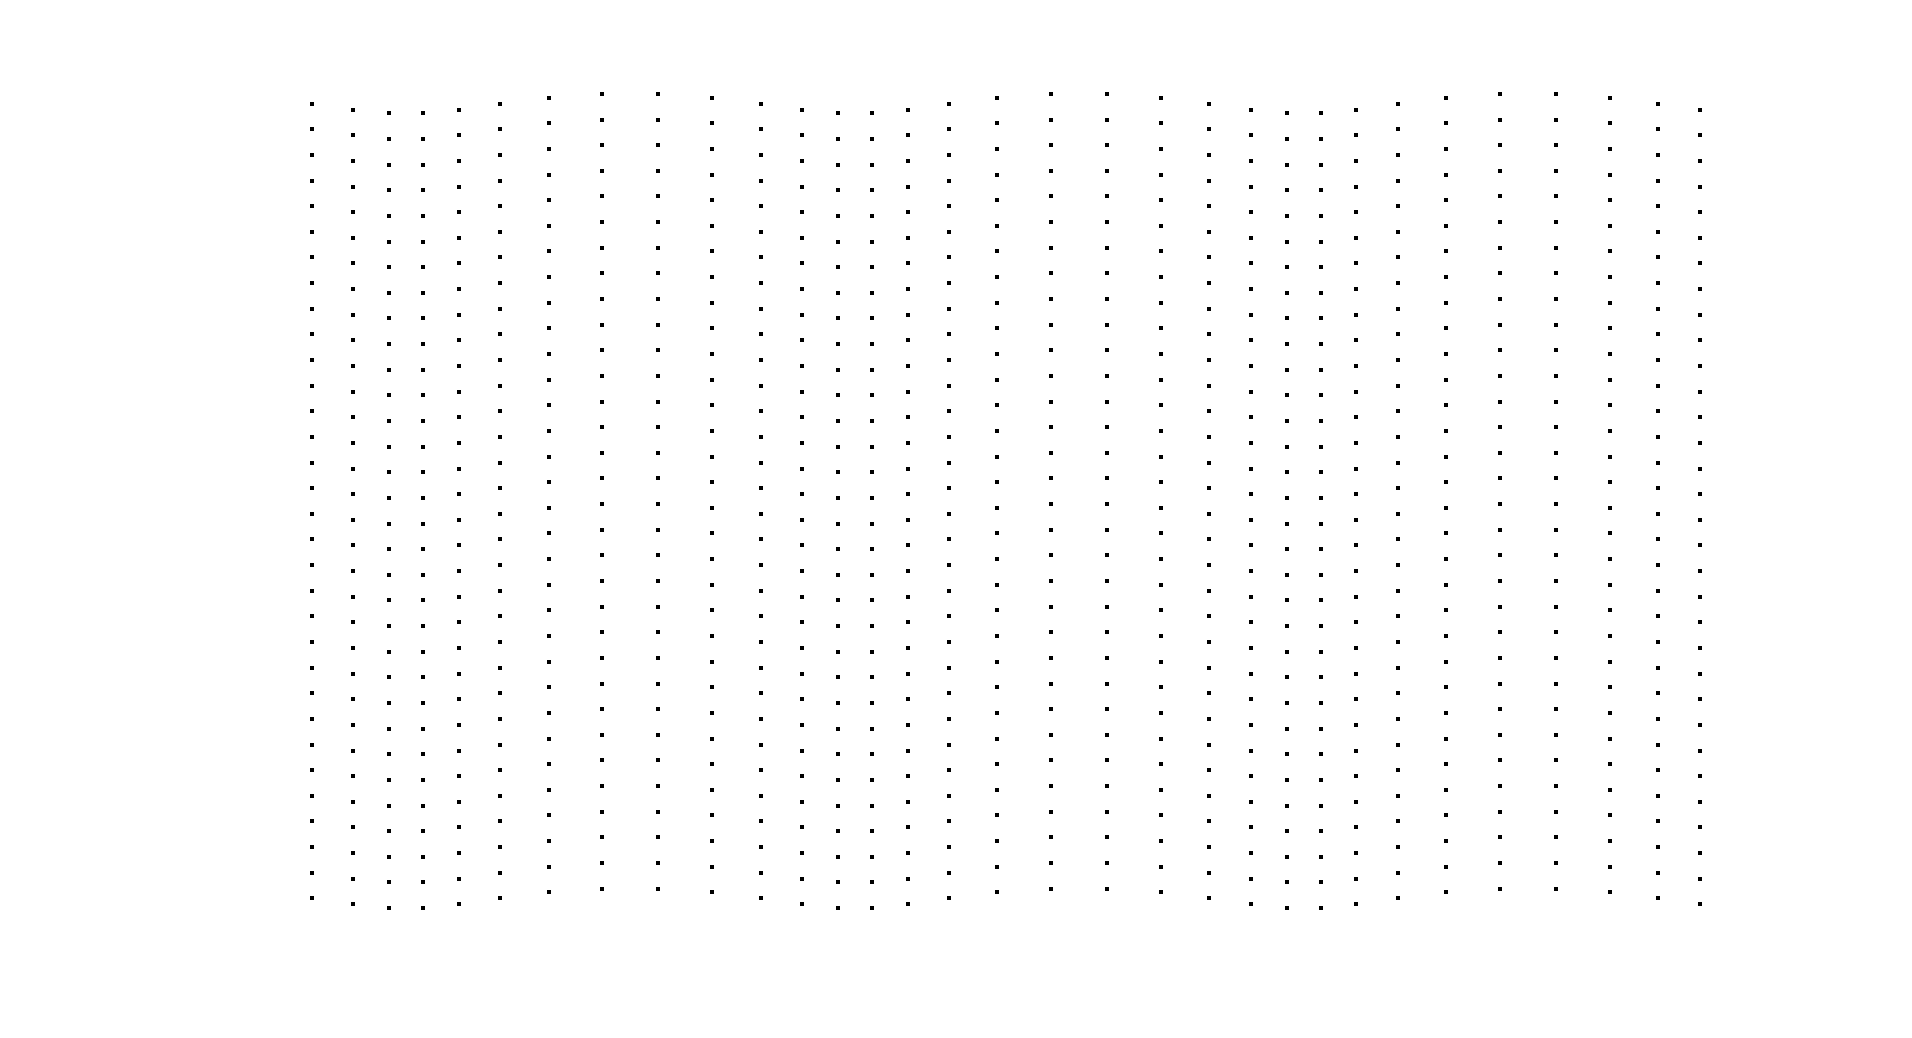

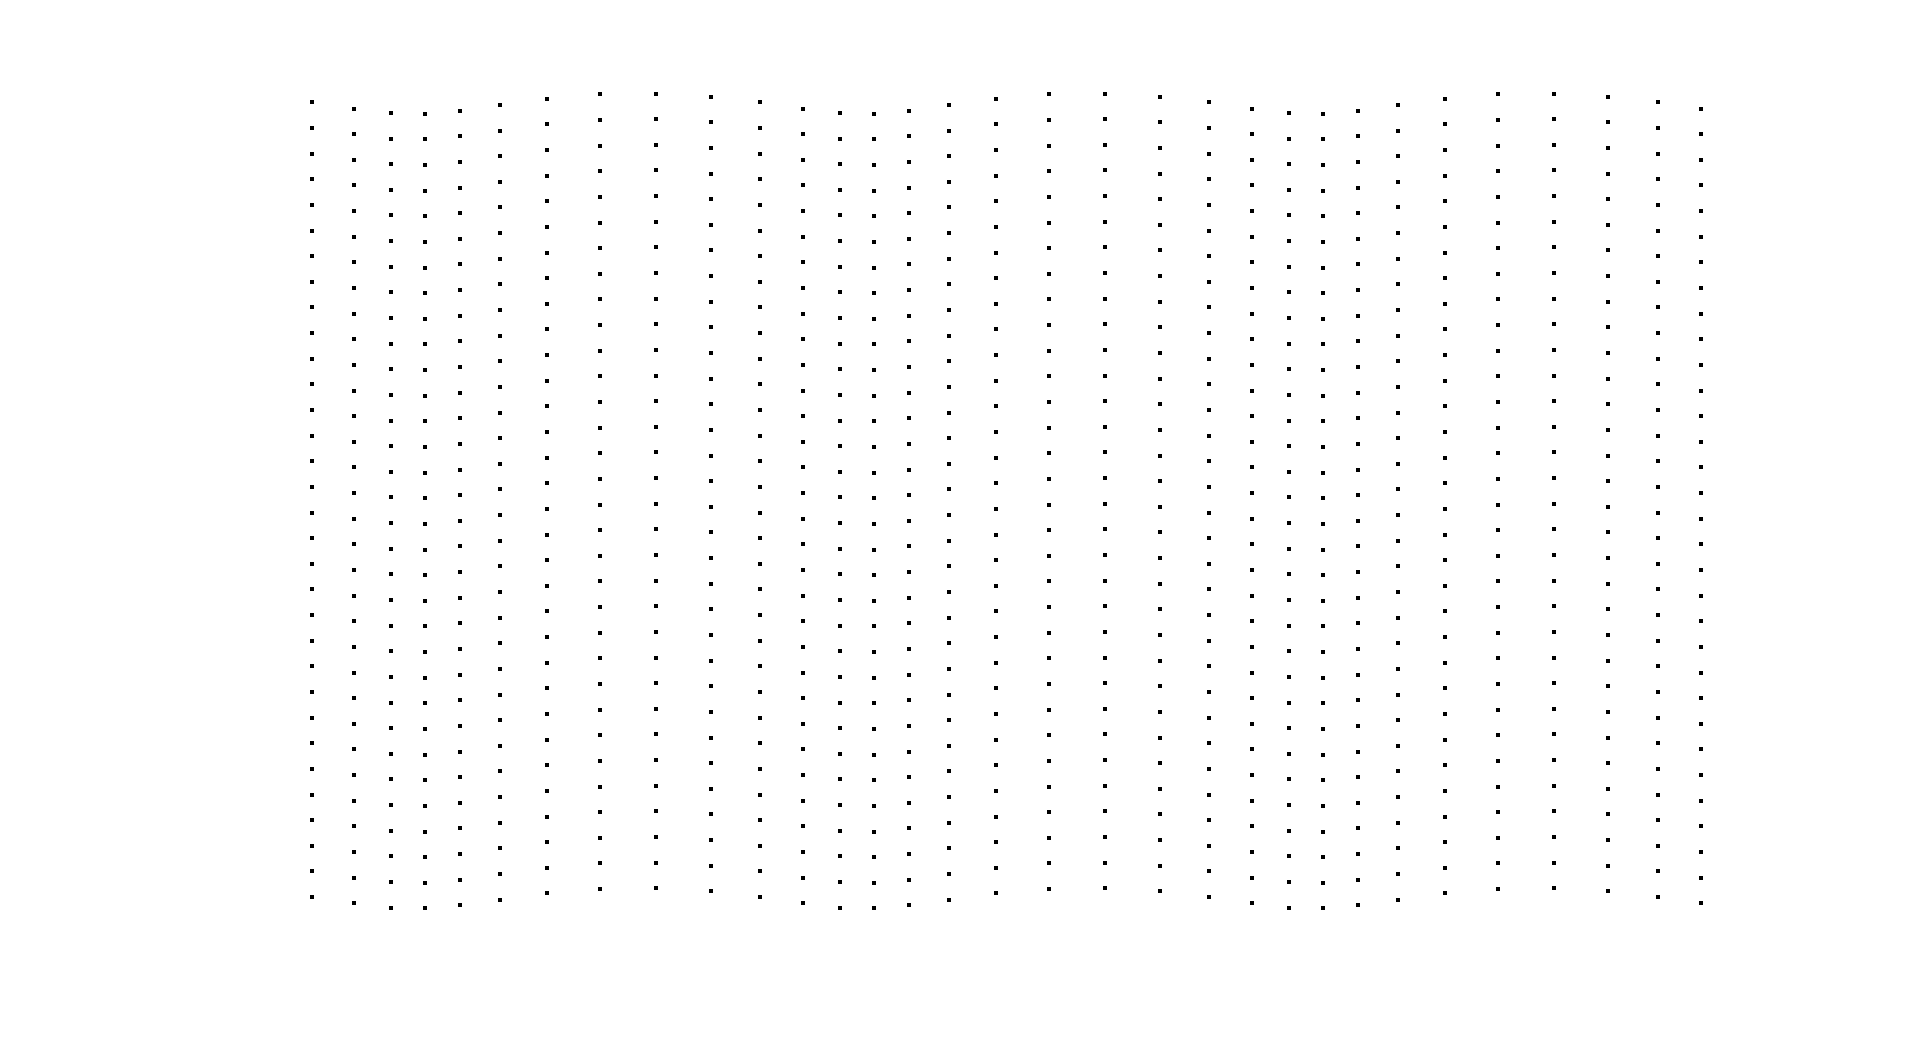

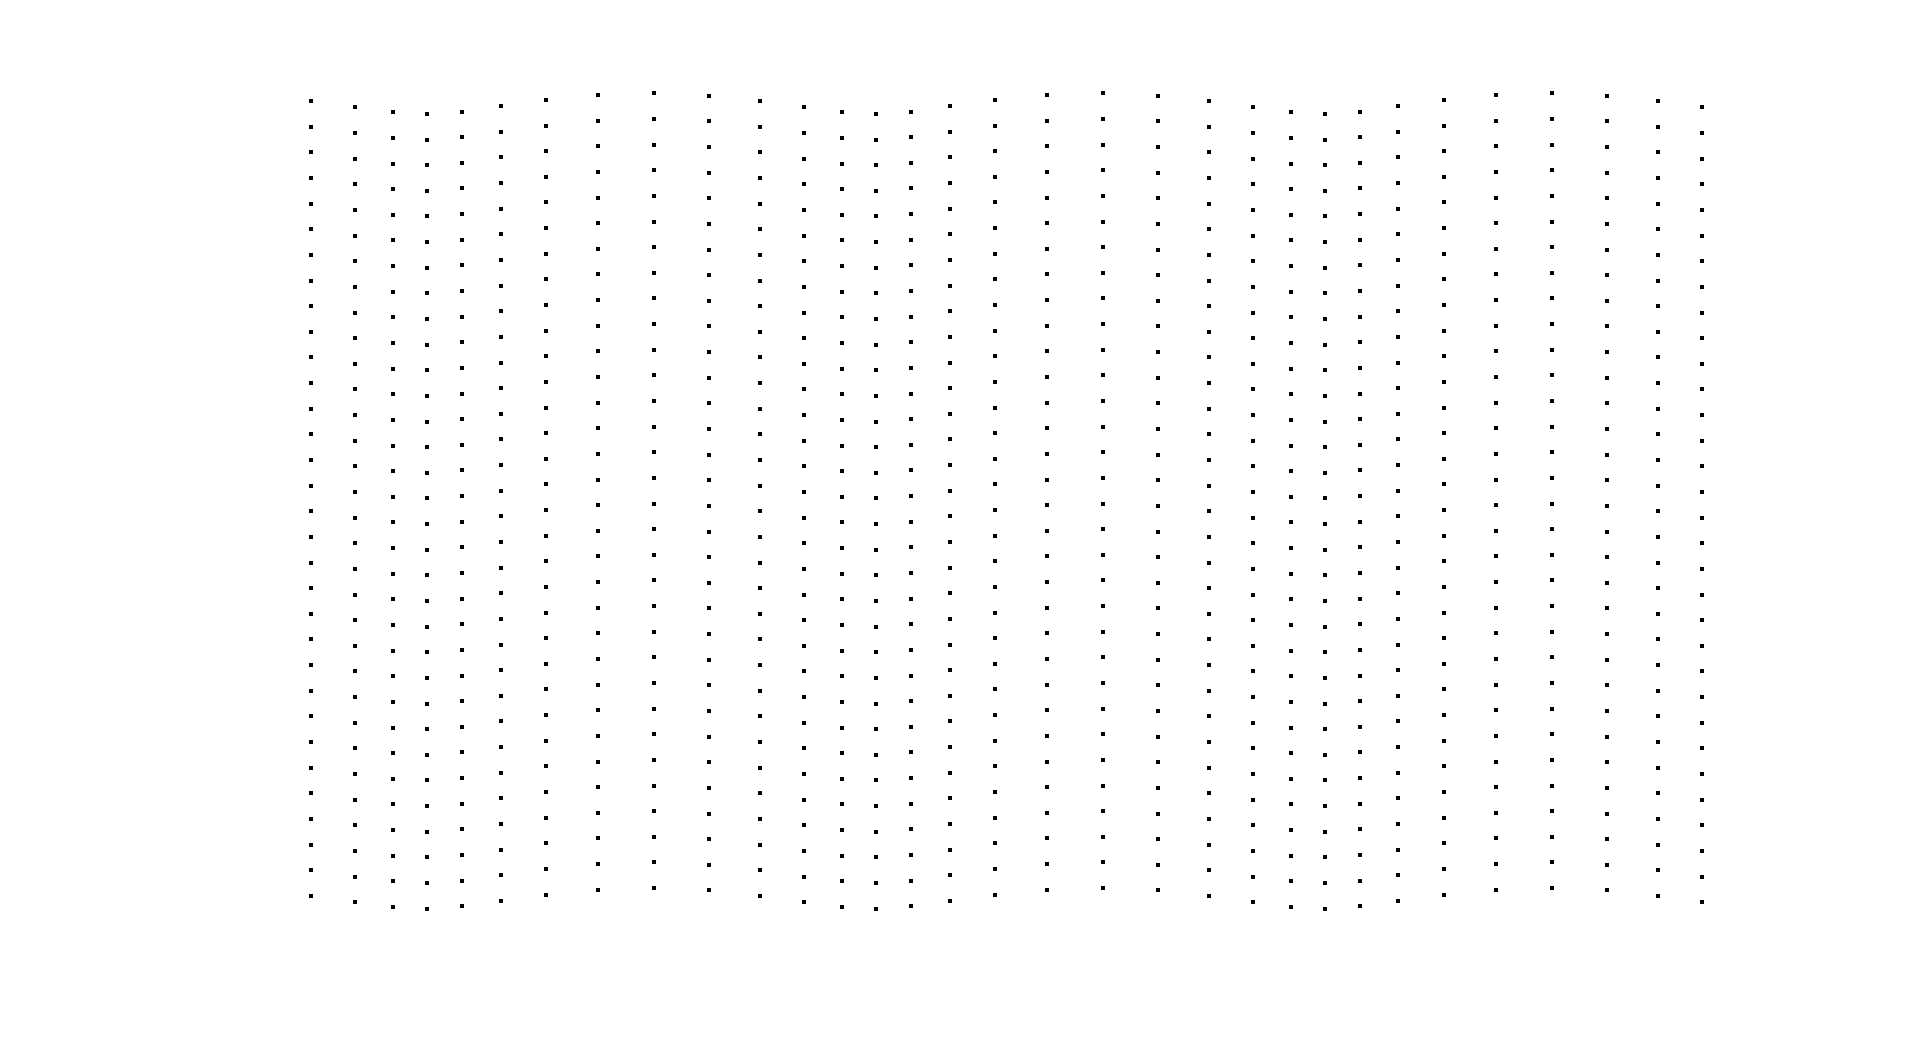

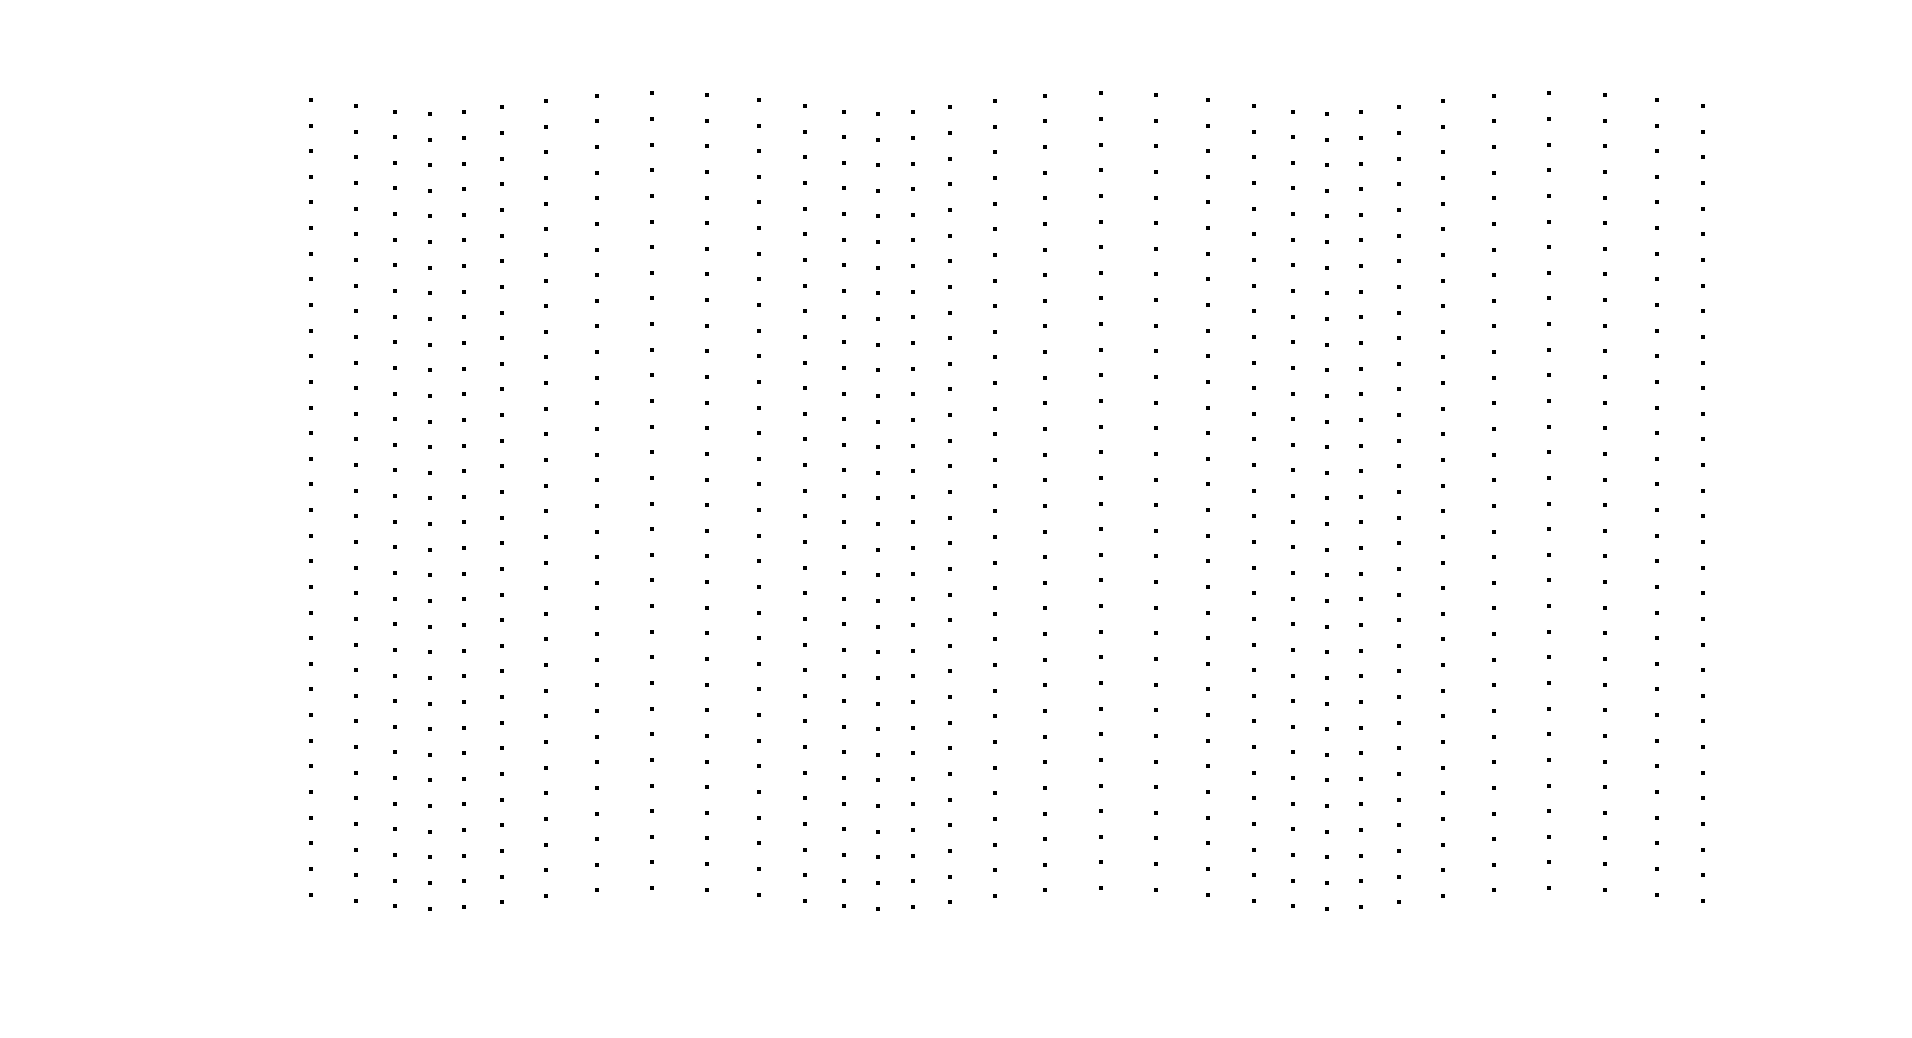

% -------------------------------------------------------------------------
% INTRODUCTION:
% This script visualizes metachronal waves using rotating dots. It creates
% synthetic videos of dots oscillating in phase and space, simulating the
% complex wave patterns that can emerge. These synthetic videos with known
% wave patterms will later be used verify the effectiveness of DDM analysis
% in detecting wave characteristics.
% -------------------------------------------------------------------------

clc
clear

% ==============================
% Initial Configuration Settings
% ==============================

% Scaling and visualization parameters
scale = 512*4;  % visualization scale
wheat_line_num = 8*4;  % number of wheat lines
wheat_gap = 200;  % gap between each wheat representation
wheat_radius = wheat_gap*0.4;  % radius of each wheat representation

% Simulation time parameters
framerate = 10;  % frames per second for the video
time = 10;  % total time for the simulation

% Frequency settings for wheat oscillation
freq = double(0.2);  % time frequency for oscillation in Hz, s^-1
f_x  = double(0.1);  % spatial frequency along x-axis
f_y  = double(0);     % spatial frequency along y-axis
f_xy = double(0);    % combined spatial frequency (interaction term)

% Decay settings to simulate damping
tau_c = 10;      % time decay constant
x_c = 500;       % decay center along x-axis (in pixels)
y_c = 500;       % decay center along y-axis (in pixels)
ifTimeDecay = 0; % flag to enable/disable time-based decay
ifSpaceDecay = 0;% flag to enable/disable space-based decay

% Grid configuration for plotting
xy = [1:wheat_line_num]*wheat_gap;
[X, Y] = meshgrid(xy);

% Output directory for the videos
output_path = ''; 

% ================================
% Video Creation and Visualization
% ================================

% Generate phase matrix without propagation
[phase_matrix, video_name] = make_video_matrix_no_propagation(wheat_line_num, framerate,...
    time, freq, f_x, f_y, f_xy, tau_c, x_c, y_c,...
    ifTimeDecay, ifSpaceDecay);

% Create the synthetic video with the generated phase matrix
make_synthetic_video(X, Y, phase_matrix, wheat_line_num, wheat_gap, wheat_radius, scale, framerate, video_name, output_path); 


% Define the directory where the generated videos will be saved
output_path='videos/';

% Set the spatial resolution scale for the visualization
scale = 512;

% Define the frame rate for the generated video
framerate = 10;

% Define the duration of the video in seconds
time = 10;

% List of frequencies (in Hz) for which videos will be generated
freq_list = double([0.2,0.3]);  % Frequency in Hz, s^-1

% List of spatial frequencies (in pixel^-1) along the x-axis for which videos will be generated
f_x_list  = double([0,0.02,0.05,0.1,0.2]);

% List of spatial frequencies (in pixel^-1) along the y-axis for which videos will be generated
f_y_list  = double([0,0.02,0.05,0.1,0.2]);

% List of combined spatial frequencies for x and y (in pixel^-1) for which videos will be generated
f_xy_list = double([0,0.01,0.04]);

% Flag to determine if there's a time-based decay applied. 0 means no time decay.
ifTimeDecay = 0;

% Flag to determine if there's a space-based decay applied. 0 means no space decay.
ifSpaceDecay = 0;

% Iterate over each combination of frequencies to generate corresponding videos
for freq=freq_list
    for f_x=f_x_list
        for f_y=f_y_list
            for f_xy=f_xy_list
                
                % Compute the phase matrix for the current frequency combination
                [phase_matrix,video_name] = make_video_matrix_no_propagation(wheat_line_num, framerate,...
                    time, freq, f_x, f_y, f_xy, tau_c, x_c, y_c,...
                    ifTimeDecay, ifSpaceDecay);
                
                % Generate and save the video for the current frequency combination
                make_synthetic_video(X, Y, phase_matrix, wheat_line_num, wheat_gap, wheat_radius, framerate, video_name, output_path); 
                
            end
        end
    end
end


% ==================================
% Functions for Video and Matrix Creation
% ==================================


function [A,video_name] = make_video_matrix_no_propagation(wheat_line_num, framerate,...
    time, freq, f_x, f_y, f_xy, tau_c, x_c, y_c,...
    ifTimeDecay, ifSpaceDecay)
    
    % Define time steps and frame calculations
    time_step = 1/framerate;
    frame_num = int8(time/time_step);
    frame_c = double(tau_c/time_step);
    A = zeros([wheat_line_num,wheat_line_num,frame_num]);
    
    % Calculate the phase values for each frame
    parfor t = 1:frame_num
        for j = 1:wheat_line_num
            for i = 1:wheat_line_num
                A(i,j,t) = exp(-ifSpaceDecay*j/x_c-ifSpaceDecay*i/y_c-ifTimeDecay*double(t)/frame_c)*(2*pi*freq*time_step*double(t)-2*pi*f_x*j-2*pi*f_y*i+2*pi*f_xy*i*j);
            end    
        end
    end
    
    % Construct video name based on parameters
    [x_c,y_c,tau_c] = deal(ifSpaceDecay*x_c,ifSpaceDecay*y_c, ifTimeDecay*tau_c);
    video_name = ['fx_' num2str(f_x,3) '_fy_' num2str(f_y,3) ...
        '_fxy_' num2str(f_xy,5) '_tauc_' num2str(tau_c) ...
        '_xc_' num2str(x_c) '_yc_' num2str(y_c) '_freq_' ...
        num2str(freq) '_gray'];
end

function [] = make_synthetic_video(X, Y, phase_matrix, wheat_line_num, wheat_gap, wheat_radius, scale, framerate, video_name, output_path)
    % Initialize video object
    output = [output_path 'large_' video_name];
    VidObj = VideoWriter(output, 'MPEG-4'); % set your file name and video compression
    VidObj.FrameRate = framerate;  % set your frame rate
    open(VidObj);
 
    % Iterate over each frame and generate the dot visualizations
    for t = 1:size(phase_matrix, 3)
        current_phase_matrix = phase_matrix(:,:,t);
        figure(t)  
        set(gcf,'position',[0,0,scale,scale])
        x_offset = wheat_radius*cos(current_phase_matrix);
        y_offset = wheat_radius*sin(current_phase_matrix);
        current_X = X+x_offset;
        current_Y = Y+y_offset;
        plot(current_X, current_Y, '.k','linewidth',3);
        xlim([0,(wheat_line_num+1)*wheat_gap]);
        ylim([0,(wheat_line_num+1)*wheat_gap]);
        axis off; 
        hold off
        frame = getframe;
        drawnow
        writeVideo(VidObj, frame);
    end
    
    % Close the video object after all frames are written
    close(VidObj);
end